# **Visión Artificial - Sistemas de Visión Artificial**

# **Práctica 3. Segmentación de imágenes (I)**

**Autor(es): Joseph Principe Pajuelo Condori**

**Fecha: 23/10/2026**

El **objetivo** principal de esta práctica es familiarizarse con las técnicas de segmentación de imágenes:

- Desde métodos supervisados, que utilizan información previa sobre las clases para determinar los parámetros de la segmentación, hasta métodos no supervisados, que obtienen dichos parámetros automáticamente a partir de los datos.

- Técnicas basadas en el histograma, técnicas de agrupamiento (*clustering*), técnicas basadas en regiones y técnicas basadas en bordes. 

- Basadas en métodos lineales y no lineales de clasificación de cada píxel de la imagen en la región que le corresponda.

 A lo largo de la práctica se solicitará que: 

- Se apliquen, de forma práctica algunas de las técnicas de segmentación estudiadas, verificando la problemática y limitaciones de las mismas.

- Se comparen unas técnicas de segmentación con otras, analizando sus resultados.

- Se distinga la segmentación supervisada frente a la no supervisada.

- Se diferencie la segmentación basada en técnicas lineales frente a no lineales.

Se recomienda realizar pruebas adicionales (modificando parámetros, utilizando otras imágenes que resalten algún efecto del procesamiento, etc.), analizar los problemas surgidos en la ejecución de la práctica y solución proporcionada, etc. Realice cada ejercicio como sección independiente, visualizando los resultados conjuntamente con subplot cuando sea conveniente, e insertando instrucciones para cerrar ventanas (*close all*), eliminar las variables del *workspace *(*clear all*) y pausar (*pause*), donde considere necesario. 

**Ejercicios propuestos:**

**1. Segmentación global supervisada basada en el histograma:**

- Abra la imagen "`esferas.jpg`".

- Conviértala en imagen en niveles de gris.

- Calcule y muestre el histograma de la imagen en niveles de gris.

- A la vista del histograma, utilice tantos umbrales como sean necesarios, con los valores adecuados para separar las distintas clases (ignorando el efecto de sombras y brillos). Puede introducirlos con un control deslizante (*numeric slider*) o pidiéndolos en el prompt de Matlab con la instrucción: umbral = input('Introduce valor del umbral X a la vista de la figura del histograma '). 

- Visualice la segmentación.

- ¿Es fácil segmentar los distintos objetos? ¿Es fácil aislar la esfera de color azul? **Justifique su respuesta.                                                                             La dificultad va depender de la visualizacion del histograma, en caso de tener unos picos bien definidos sera sencillo establecer los umbrales, en caso contrario la dificultad aumentara para poder especificar los umbrales correctos para la separacion de colores. En este caso la esfera de color azul tiene una complejidad al estar tambien representada con las sombras de las esferas asi que es complicado solo aislar el color azul.**

- Visualice la imagen en color y muestre por separado las componentes R, G y B y el histograma de cada componente. Segmente la esfera azul a partir del histograma de la componente más conveniente. ¿Es fácil de segmentar en este caso? ¿Qué conclusión puede extraer sobre la importancia de elegir adecuadamente las características utilizadas para segmentar?.                                                                                                                                             **Hacer la segmentacion es sencillo debido a que al ser RGB podemos deducir los umbrales de separacion facilmente, armando una matriz en base a las funciones 1,2,3 pertenecientes a la imagen.**

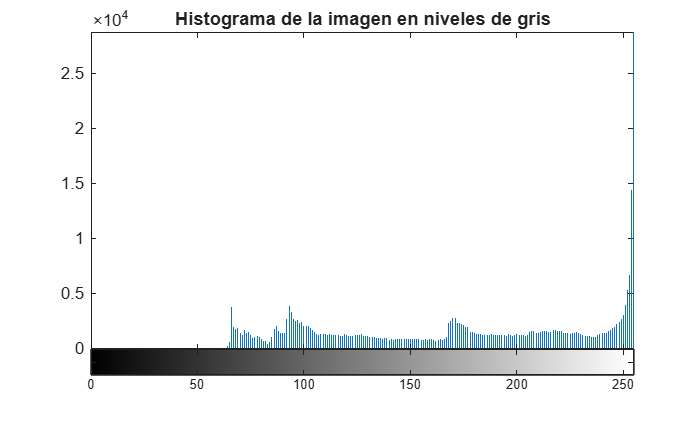

%% Practica 3 - Segmentacion global

clear; close all; clc;
% 1. Cargar imagen
I_rgb = imread('Esferas.jpg');
% 2. Convertir a escala de grises
I_gray = rgb2gray(I_rgb);
% 3. Histograma de la imagen a niveles de gris
figure('Name', 'Ejercicio 1: Histograma en Grises');
imhist(I_gray);
title('Histograma de la imagen en niveles de gris');

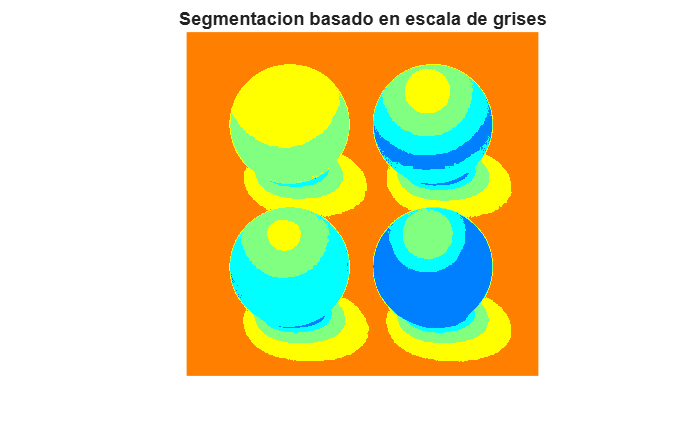

% 4. Umbralizacion global
% A la vista del histograma seleccionamos umbrales empiricos para separar
% clases
% umbral1 = input('Introduce 1 umbral: ');
% umbral2 = input('Introduce 2 umbral: ');

% Umbrales
T1 = 90;
T2 = 120;
T3 = 180;
T4 = 240;
% Segmentacion multiclase por niveles de intensidad
I_seg_gray = zeros(size(I_gray));
I_seg_gray(I_gray <= T1) = 1;
I_seg_gray(I_gray > T1 & I_gray <= T2) = 2;
I_seg_gray(I_gray > T2 & I_gray <= T3) = 3;
I_seg_gray(I_gray > T3 & I_gray <= T4) = 4;
I_seg_gray(I_gray > T4) = 5;
% 5. Visualizacion de la segmentacion basado en grises
figure('Name', 'Ejercicio 1: Segmentacion Global en Grises');
imshow(label2rgb(I_seg_gray));
title('Segmentacion basado en escala de grises');

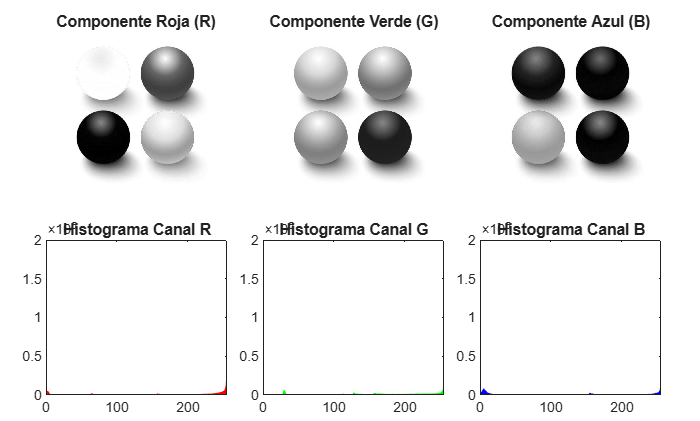

% 6,7. Analisis de las componentes de color R,G,B
% Separacion de canales de colores
R = I_rgb(:,:,1);
G = I_rgb(:,:,2);
B = I_rgb(:,:,3);
figure('Name', 'Ejercicio 1: Componentes RGB e Histogramas');
tiledlayout(2, 3, 'TileSpacing', 'compact', 'Padding', 'compact');

nexttile; imshow(R); title('Componente Roja (R)');
nexttile; imshow(G); title('Componente Verde (G)');
nexttile; imshow(B); title('Componente Azul (B)');

nexttile; 
[countsR, binLocationsR] = imhist(R);
area(binLocationsR, countsR, 'FaceColor', 'r', 'EdgeColor', 'none');
title('Histograma Canal R'); xlim([0 255]);

nexttile; 
[countsG, binLocationsG] = imhist(G);
area(binLocationsG, countsG, 'FaceColor', 'g', 'EdgeColor', 'none');
title('Histograma Canal G'); xlim([0 255]);

nexttile; 
[countsB, binLocationsB] = imhist(B);
area(binLocationsB, countsB, 'FaceColor', 'b', 'EdgeColor', 'none');
title('Histograma Canal B'); xlim([0 255]);

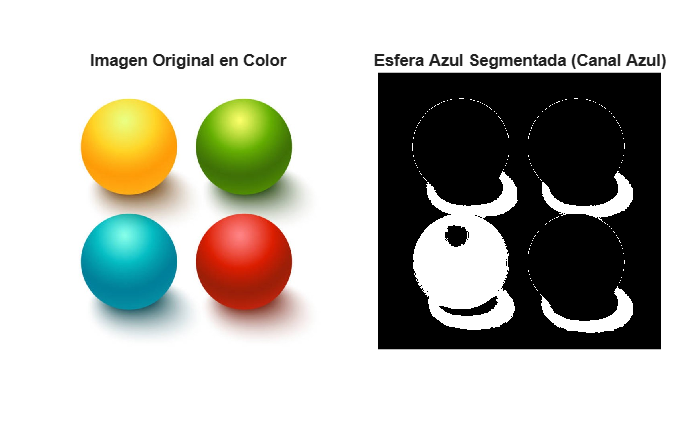


% 8. Segmentacion especifica
min_azul = 150;
max_azul = 220;

I_esfera_azul = (B >= min_azul) & (B <= max_azul);
figure('Name', 'Ejercicio 1: Aislamiento de la Esfera Azul');
tiledlayout(1, 2, 'TileSpacing', 'compact', 'Padding', 'compact');

nexttile; imshow(I_rgb);         title('Imagen Original en Color');
nexttile; imshow(I_esfera_azul); title('Esfera Azul Segmentada (Canal Azul)');

**2. Umbralización global no supervisada: método de Otsu:**

- **Umbralice **la imagen "eight.tif"** con la función *****imbinarize***, utilizando un umbral global calculado previamente con la función ***graythresh*** de Matlab (método no supervisado: no requiere la observación del usuario del histograma, ni la elección de umbrales a partir del mismo): 

                    *   La función *graythresh *utiliza el método Otsu para calcular automáticamente un umbral global, maximizando la varianza entre clases o minimizando la varianza dentro de las clases.

                    *  La función *imbinarize *umbraliza imágenes en niveles de gris. Si la imagen original está en color es necesario transformarla previamente a niveles de gris, con la función correspondiente dependiendo de su formato (*rgb2gray*, etc.).  

                         level = graythresh(I);

                         BW = *imbinarize*(I,level);

                         figure, imshow(BW)

- ¿Funciona correctamente la segmentación no supervisada con la imagen "eight.tif"? ¿Por qué?                                                                                            **Funciona muy bien debido a que la imagen tiene picos claros y separados.**

- Pruebe con otras imágenes de Matlab con histogramas de distintas formas ¿*graythresh* consigue segmentar adecuadamente todas las imágenes? En caso negativo, analice qué características presentan los histogramas de las imágenes para las que funciona mejor o peor.

- **El algoritmo otsu tiene problemas cuando las imagenes contienen sombras o iluminaciones variadas, histogramas no bimodales o que la imagen su objeto sea demasiado pequeño a comparacion del fondo, haciendo que el algoritmo lo ignore.**

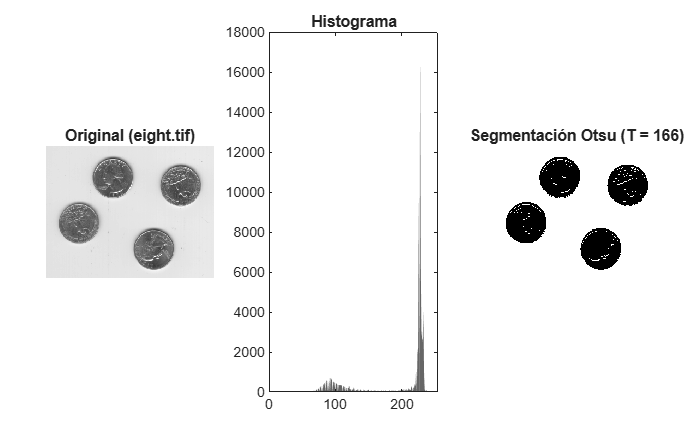

%% Practica 3. Ejercicio 2: Umbralizacion global no supervizada
clearvars -except I_rgb I_gray I_seg_gray I_esfera_azul;
%close all;
% Lectura de imagen
I_eight = imread('eight.tif');
% Obtencion del umbral optimo mediante otsu
level = graythresh(I_eight);
% Conversion binaria mediante umbral (blanco/negro)
BW_eight = imbinarize(I_eight, level);
figure('Name', 'Ejercicio 2: Umbralización de Otsu sobre eight.tif');
tiledlayout(1, 3, 'TileSpacing', 'compact', 'Padding', 'compact');

nexttile; imshow(I_eight);   
title('Original (eight.tif)');

% 2. Histograma
nexttile; 
[counts, binLocations] = imhist(I_eight);
area(binLocations, counts, 'FaceColor', [0.4 0.4 0.4], 'EdgeColor', 'none'); % Color gris elegante
title('Histograma'); 
xlim([0 255]);

% 3. Imagen Segmentada mostrando el umbral real de 0 a 255
nexttile; imshow(BW_eight);  
title(['Segmentación Otsu (T = ', num2str(round(level * 255)), ')']);

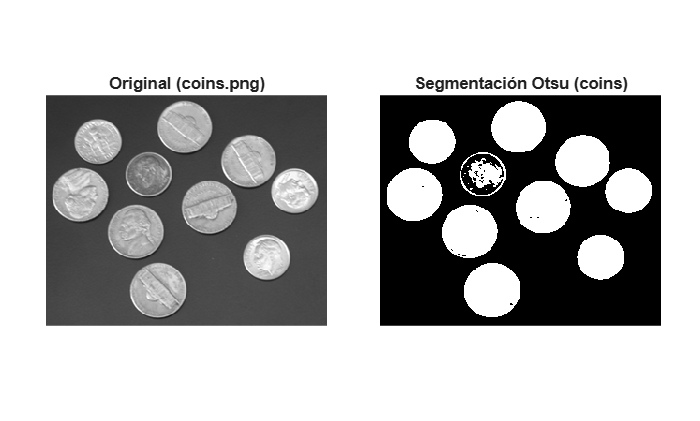

% Pruebas adicionales con otras imágenes de MATLAB
I_coins = imread('coins.png');
level_coins = graythresh(I_coins);
BW_coins = imbinarize(I_coins, level_coins);

figure('Name', 'Ejercicio 2: Prueba adicional con coins.png');
tiledlayout(1, 2, 'TileSpacing', 'compact', 'Padding', 'compact');

nexttile; imshow(I_coins);  title('Original (coins.png)');
nexttile; imshow(BW_coins); title('Segmentación Otsu (coins)');

**3. Compare los dos apartados anteriores: umbralización supervisada frente a no supervisada, indicando las ventajas e inconvenientes de cada una.**

**En la umbralizacion no supervisada, el algoritmo no sabe què es un objeto ni què es el fondo; simplemente agrupa los pixeles basándose en sus similitudes matemáticas (niveles de grises, varianza y distancia). Como inconvenientes tiene que es muy sencible a imperfecciones y falta de contexto semántico.**

**En la umbralizacion supervisada, requiere un entrenamiento previo posterior a este, ya es altamente robusto y tiene una precisión semántica. Como inconvenientes sería la dependencia de datos, el sobreajuste y el alto costo computacional. **

**4. Opcional. Segmentación no lineal (mediante modelos gaussianos) con más de dos clases. **

En ambos casos se considerará que a la entrada se pueden utilizar imágenes de cualquier tamaño y tipo (indexadas, en color o en niveles de gris) que serán siempre convertidas a niveles de gris en primer lugar. La salida deberá ser una imagen de etiquetas que permita distinguir las distintas clases obtenidas.

- Implemente un programa que realice la segmentación supervisada por modelos gaussianos (no lineal) para un número de clases superior a 2. 

- Implemente un programa que realice la segmentación no supervisada por modelos gaussianos (no lineal) para un número de clases superior a 2. 

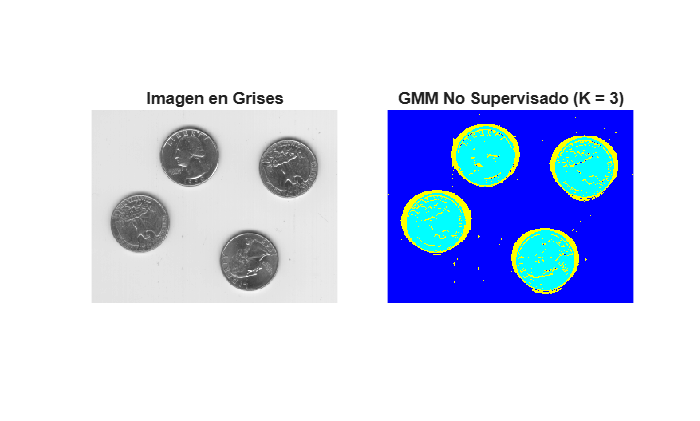

%% Opcional no supervisado, algoritmo EM (Expectation-Maximization)

% Conversion a escala de grises, independientemente del tipo de imagen
[I_in, map] = imread('eight.tif');
if ndims(I_in) == 3
    I_gray = rgb2gray(I_in);
elseif ~isempty(map)
    I_gray = im2gray(I_in, map);
else
    I_gray = I_in;
end
% Conversion de pixeles
I_double = double(I_gray);
% Especificacion del numero de clases
k = 3;
% Aplanando la matriz bidimensional convirtiendo en un único vertor
pixeles = I_double(:);
% Parametros de control (reintentos)
opciones = statset('MaxIter', 500);
% Campanas de gauss (distribucion normal)
gmm_modelo = fitgmdist(pixeles, k, 'RegularizationValue', 0.1, 'Options', opciones);
% Evaluacion de los pixeles mediante el modelo ya entrenado
idx = cluster(gmm_modelo, pixeles);
% Convierte el vector a matriz bidimensional
I_seg_gmm = reshape(idx, size(I_gray));

figure('Name', 'Segmentación GMM No Supervisada');
tiledlayout(1, 2, 'TileSpacing', 'compact');

nexttile; imshow(I_gray); title('Imagen en Grises');
nexttile; imshow(label2rgb(I_seg_gmm)); title(['GMM No Supervisado (K = ', num2str(k), ')']);

%% Segmentacion supervizada

I_in = imread('eight.tif'); 

% 1. Conversión robusta a escala de grises
if ndims(I_in) == 3, I_gray = rgb2gray(I_in); else, I_gray = I_in; end
I_double = double(I_gray);

% 2. Definir número de clases
K = 3; 

% Matrices para almacenar los parámetros aprendidos de cada clase
medias = zeros(K, 1);
varianzas = zeros(K, 1);

% 3. Fase de Entrenamiento (Supervisión)
fprintf('Por favor, selecciona regiones de entrenamiento en la imagen.\n');

Por favor, selecciona regiones de entrenamiento en la imagen.


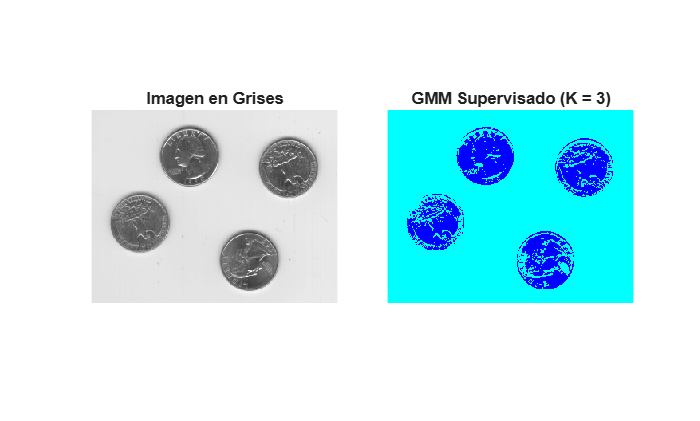

figure('Name', 'Fase de Entrenamiento: Selecciona Regiones');
imshow(I_gray);

for k = 1:K
    title(['Selecciona con clics la región para la Clase ', num2str(k), ' (Doble clic al terminar)']);

    % Crea una máscara interactiva en la pantalla
    mascara = roipoly(); 

    % Extraer los píxeles caídos dentro de esa máscara
    pixeles_entrenamiento = I_double(mascara);

    % Calcular (APRENDER) de forma supervisada los parámetros gaussianos
    medias(k) = mean(pixeles_entrenamiento);
    varianzas(k) = var(pixeles_entrenamiento);
end
close; % Cerrar ventana de entrenamiento

% 4. Fase de Clasificación (Clasificador Gaussiano de Máxima Verosimilitud)
[filas, columnas] = size(I_gray);
I_seg_supervisada = zeros(filas, columnas);

% Evaluamos la probabilidad de cada píxel en cada una de las K funciones Gaussianas
probabilidades = zeros(filas * columnas, K);
pixeles_todos = I_double(:);

for k = 1:K
    % Ecuación de la densidad de probabilidad Gaussiana (1D)
    mu = medias(k);
    sig2 = varianzas(k);

    probabilidades(:, k) = (1 / sqrt(2 * pi * sig2)) * exp(-((pixeles_todos - mu).^2) / (2 * sig2));
end

% Asignar el píxel a la clase que tenga la probabilidad MÁXIMA
[~, idx_max] = max(probabilidades, [], 2);

% Reconstruir mapa de etiquetas
I_seg_supervisada = reshape(idx_max, size(I_gray));

% 5. Visualización
figure('Name', 'Segmentación GMM Supervisada');
tiledlayout(1, 2, 'TileSpacing', 'compact');

nexttile; imshow(I_gray); title('Imagen en Grises');
nexttile; imshow(label2rgb(I_seg_supervisada)); title(['GMM Supervisado (K = ', num2str(K), ')']);